# `DEMO_02b:`   4-bar linkage analysis - `dynamics`

Let's derive the Equations of Motion (EoM) of a 4bar linkage - see Figure_01 below.  We'll refer to the system **input** as $\theta$.  We'll look specifically at machines where the input crank can rotate a FULL revolution.

**Figure 01:  the 4bar linkage**

  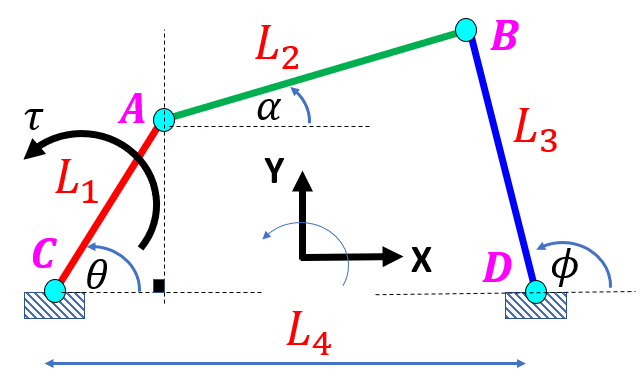

The approach that we'll take is to incorprate the 2 kinematic constraints equations into our Lagrangian derivation, ie, the constraint equations are:

- 
$$X\;\textrm{direction}\Longrightarrow \;\;\;\;\;\;\;\;f\left(\theta ,\;\alpha ,\;\phi \right)=\;\;0\;\;=\;{\;\;\;L}_1 \;\ldotp \cos \left(\theta \right)\;\;+\;L_2 \ldotp \cos \left(\alpha \right)\;-\;L_3 \ldotp \cos \left(\phi \right)-\;L_4 \;\;\;$$


- 
$$Y\;\mathrm{direction}\Longrightarrow \;\;\;\;\;\;\;\;\;g\left(\theta ,\;\alpha ,\;\phi \right)=\;\;0\;\;=\;\;\;\;\;L_1 \ldotp \mathrm{sin}\left(\theta \right)\;\;\;+\;\;L_2 \ldotp \mathrm{sin}\left(\alpha \right)\;-\;\;\;\;L_3 \ldotp \mathrm{sin}\left(\phi \right)\;$$


So our Lagrangian derivation becomes:

- 
$$\frac{d}{\mathrm{dt}}\frac{\partial L}{\partial \dot{q_k } }\;\;\;-\;\;\frac{\partial L}{\partial q_k }\;\;\;=\;\;\;Q_k \;\;+\;\;\;\frac{\partial }{\partial q_k }\left(\lambda_1 \ldotp f\;\;\;+\;\;\;\;\lambda_2 \ldotp g\;\right)$$


`Bradley Horton : 11-Nov-2019, bhorton@mathworks.com`

### Define the main collection of symbols

syms L_1  L_2  L_3  L_4  real
syms I_1  I_2  I_3       real
syms m_1  m_2  m_3  g    real

syms tau_1              real
syms lambda_1  lambda_2 real


syms theta  theta_dot  theta_ddot real
syms alpha  alpha_dot  alpha_ddot real
syms   phi    phi_dot    phi_ddot real

syms THETA(t)  ALPHA(t)  PHI(t)

#### Define the main and HOLDER symbol lists

MAIN_sym_list = [      THETA(t),           ALPHA(t),           PHI(t)      , ...
                  diff(THETA(t),t,1), diff(ALPHA(t),t,1), diff(PHI(t),t,1) , ...
                  diff(THETA(t),t,2), diff(ALPHA(t),t,2), diff(PHI(t),t,2) 
                ];
            
HOLD_sym_list = [   theta,         alpha,         phi        , ...   
                    theta_dot,     alpha_dot,     phi_dot    , ...
                    theta_ddot,    alpha_ddot,    phi_ddot
                ];

#### Define the TRANSLATIONAL and ROTATIONAL Kinetic Energy

 v1_col = diff(  [ (0.5*L_1*cos(THETA(t)) );   (0.5*L_1*sin(THETA(t)) )  ]    ); 
 v3_col = diff(  [ (0.5*L_3*cos(  PHI(t)) );   (0.5*L_3*sin  (PHI(t)) )  ]    ); 
 v2_col = diff(  [ (L_1*cos(THETA(t)) + 0.5*L_2*cos(ALPHA(t))); ...
                   (L_1*sin(THETA(t)) + 0.5*L_2*sin(ALPHA(t)))  ]    ); 

 KE = 0.5*(  m_1*v1_col.'*v1_col      +  m_2*v2_col.'*v2_col      +   m_3*v3_col.'*v3_col    )  + ...
      0.5*(  I_1*diff(THETA(t),t)^2   +  I_2*diff(ALPHA(t),t)^2   +   I_3*diff(PHI(t),t)^2   );

#### Define the POTENTIAL energy

  PE = g*(m_1*sin(THETA(t))*L_1/2   +   m_3*sin(PHI(t))*L_3/2   +   m_2*(L_1*sin(THETA(t)) + sin(ALPHA(t))*L_2/2)  );

#### Define the LAGRANGIAN 

THE_L = KE - PE;

Apply Lagranges equation

- 
$$\frac{d}{\textrm{dt}}\frac{\partial L}{\partial \dot{q_k } }\;\;\;-\;\;\frac{\partial L}{\partial q_k }\;\;\;=\;\;\;Q_k$$


EQ1_LHS =   LOC_do_lagrange(THE_L, [theta, theta_dot], MAIN_sym_list, HOLD_sym_list);
EQ1_RHS =   tau_1;
EQ2_LHS =   LOC_do_lagrange(THE_L, [alpha, alpha_dot], MAIN_sym_list, HOLD_sym_list);
EQ2_RHS =   sym(0);
EQ3_LHS =   LOC_do_lagrange(THE_L, [phi,     phi_dot], MAIN_sym_list, HOLD_sym_list);
EQ3_RHS =   sym(0);

### Define the CONSTRAINT equations:

The angles $\left\lbrack \theta ,\;\alpha ,\;\phi \right\rbrack$ are related by the constraint equations:

- 
$$X\;\mathrm{direction}\Longrightarrow \;\;\;\;\;\;\;\;f\left(\theta ,\;\alpha ,\;\phi \right)=\;\;0\;\;=\;{\;\;\;L}_1 \;\ldotp \mathrm{cos}\left(\theta \right)\;\;+\;L_2 \ldotp \mathrm{cos}\left(\alpha \right)\;-\;L_3 \ldotp \mathrm{cos}\left(\phi \right)-\;L_4 \;\;\;$$


- 
$$Y\;\textrm{direction}\Longrightarrow \;\;\;\;\;\;\;\;\;g\left(\theta ,\;\alpha ,\;\phi \right)=\;\;0\;\;=\;\;\;\;\;L_1 \ldotp \sin \left(\theta \right)\;\;\;+\;\;L_2 \ldotp \sin \left(\alpha \right)\;-\;\;\;\;L_3 \ldotp \sin \left(\phi \right)\;$$


CONS_EQ_POS_X =   0 == L_1*cos(THETA(t)) + L_2*cos(ALPHA(t)) - L_3*cos(PHI(t)) - L_4;
CONS_EQ_POS_Y =   0 == L_1*sin(THETA(t)) + L_2*sin(ALPHA(t))                   - L_3*sin(PHI(t));

I'd like to differentiate(twice) these positional constraints to get acceleration constraints:

CONS_EQ_ACC_X      = diff(CONS_EQ_POS_X, t, 2);
CONS_EQ_ACC_Y      = diff(CONS_EQ_POS_Y, t, 2);

And use the HOLD symbols in these constraint equations:

CONS_EQ_ACC_X_HOLD = subs(CONS_EQ_ACC_X, MAIN_sym_list, HOLD_sym_list);
CONS_EQ_ACC_Y_HOLD = subs(CONS_EQ_ACC_Y, MAIN_sym_list, HOLD_sym_list);

CONS_EQ_POS_X_HOLD = subs(CONS_EQ_POS_X, MAIN_sym_list, HOLD_sym_list);
CONS_EQ_POS_Y_HOLD = subs(CONS_EQ_POS_Y, MAIN_sym_list, HOLD_sym_list);

Multiply our positional contraints by Lagrange multipliers AND add together the 2 positional contraints:

- 
$$f\left(\theta ,\;\alpha ,\;\phi \right)=\;\;0\;\;$$


- 
$$\;g\left(\theta ,\;\alpha ,\;\phi \right)=\;\;0$$


- 
$$0\;\;=\;\;\;\lambda_1 \ldotp f\left(\theta ,\;\alpha ,\;\phi \right)\;\;\;+\;\;\;\;\lambda_2 \ldotp g\left(\theta ,\;\alpha ,\;\phi \right)$$


CONS_EQ_ZERO_POS_LAMBDA = lambda_1*CONS_EQ_POS_X_HOLD  +  lambda_2*CONS_EQ_POS_Y_HOLD

$$CONS\_EQ\_ZERO\_POS\_LAMBDA = 0=\lambda_{2}\,\left(L_{2}\,\sin\left(\alpha \right)-L_{3}\,\sin\left(\varphi \right)+L_{1}\,\sin\left(\theta \right)\right)-\lambda_{1}\,\left(L_{4}-L_{2}\,\cos\left(\alpha \right)+L_{3}\,\cos\left(\varphi \right)-L_{1}\,\cos\left(\theta \right)\right)$$

### Incorporate the POSITIONAL constraints into the Lagrange equations:

We take the variation of the constraint equations and add tthese to the RHS of our Lagrangian equations, ie:

- 
$$\frac{d}{\mathrm{dt}}\frac{\partial L}{\partial \dot{q_k } }\;\;\;-\;\;\frac{\partial L}{\partial q_k }\;\;\;=\;\;\;Q_k \;\;+\;\;\;\frac{\partial }{\partial q_k }\left(\lambda_1 \ldotp f\;\;\;+\;\;\;\;\lambda_2 \ldotp g\;\right)$$


EQ1_RHS =  EQ1_RHS  +  diff( rhs(CONS_EQ_ZERO_POS_LAMBDA), theta )

$$EQ1\_RHS = \tau_{1}+L_{1}\,\lambda_{2}\,\cos\left(\theta \right)-L_{1}\,\lambda_{1}\,\sin\left(\theta \right)$$

EQ2_RHS =  EQ2_RHS  +  diff( rhs(CONS_EQ_ZERO_POS_LAMBDA), alpha )

$$EQ2\_RHS = L_{2}\,\lambda_{2}\,\cos\left(\alpha \right)-L_{2}\,\lambda_{1}\,\sin\left(\alpha \right)$$

EQ3_RHS =  EQ3_RHS  +  diff( rhs(CONS_EQ_ZERO_POS_LAMBDA), phi )

$$EQ3\_RHS = L_{3}\,\lambda_{1}\,\sin\left(\varphi \right)-L_{3}\,\lambda_{2}\,\cos\left(\varphi \right)$$

### Now define our final 5 equations:

The first 3 equations are our Lagrangian equations and the last 2 equations are our acceleration constraint equations

tmp_LHS = [EQ1_LHS; EQ2_LHS; EQ3_LHS; lhs(CONS_EQ_ACC_X_HOLD); lhs(CONS_EQ_ACC_Y_HOLD)];
tmp_RHS = [EQ1_RHS; EQ2_RHS; EQ3_RHS; rhs(CONS_EQ_ACC_X_HOLD); rhs(CONS_EQ_ACC_Y_HOLD)];

What do they look like ?

EQ_SYS = tmp_LHS == tmp_RHS

#### Convert these system equations it into the matrix form  *A.x = b* :

Let, 

- 
$$x={\left\lbrack \begin{array}{ccccc}
\theta^¨  & \alpha^¨  & \phi^¨  & \lambda_1  & \lambda_2 
\end{array}\right\rbrack }^T$$
 

now rearrange our system equations into the form:

- 
$$A\;\ldotp x\;=\;b$$


[A,b] = equationsToMatrix(EQ_SYS,[theta_ddot, alpha_ddot, phi_ddot, lambda_1, lambda_2]);

So the expressions that I'd really like are:

my_ACC_and_lambda_col = simplify( inv(A) * b );
whos my_ACC_and_lambda_col

  Name                       Size            Bytes  Class    Attributes

  my_ACC_and_lambda_col      5x1                 8  sym                



### Convert these symbolic expressions to a MATLAB function block for Simulink:

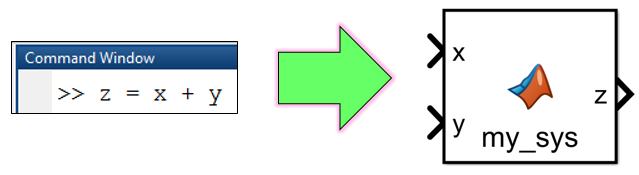

tf_i_should_create_SL_block = true;

if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'SIM_SMD_WILL_BE_DELETED';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)   
                          
    % Put BOTH equations into one block 
    BLOCK_NAME = [MODEL_NAME,'/THE_HAND_DYN_SYS'];
    matlabFunctionBlock( BLOCK_NAME, ...
                          my_ACC_and_lambda_col(1), my_ACC_and_lambda_col(2), my_ACC_and_lambda_col(3), ...
                          my_ACC_and_lambda_col(4), my_ACC_and_lambda_col(5), ...
                         'Optimize', false, ...
                         'Outputs', {'theta_DD', 'alpha_DD', 'phi_DD', 'Lambda_1', 'Lambda_2'}   );  
                     
                            % make the block YELLOW                   
   set_param( BLOCK_NAME,'BackgroundColor', '[0.996078, 1.000000, 0.705882]');     
end

Local functions only beyond this point

function the_EOM = LOC_do_lagrange(in_L, in_PV_HOLD_list, in_MAIN_list, in_HOLD_list)
   
    syms t 
    
   THE_q      = in_PV_HOLD_list(1);
   THE_qdot   = in_PV_HOLD_list(2);
    
   THE_L      = in_L;
   THE_L      = subs(THE_L, in_MAIN_list, in_HOLD_list);
   
   dLdq       = diff(THE_L, THE_q);
   
   dLdqdot    = diff(THE_L, THE_qdot);
   dLdqdot    = subs(dLdqdot, in_HOLD_list, in_MAIN_list);
   
   dt_dLdqdot = diff(dLdqdot, t);
   
   
   the_EOM    = dt_dLdqdot - dLdq;
   
   the_EOM    = subs(the_EOM, in_MAIN_list, in_HOLD_list);
      
end